% The Nelder-Mead Simplex Method  - From HW5 Question 1


Change the **objective function at the bottom of the code**

**Change the contour function at line 20. **

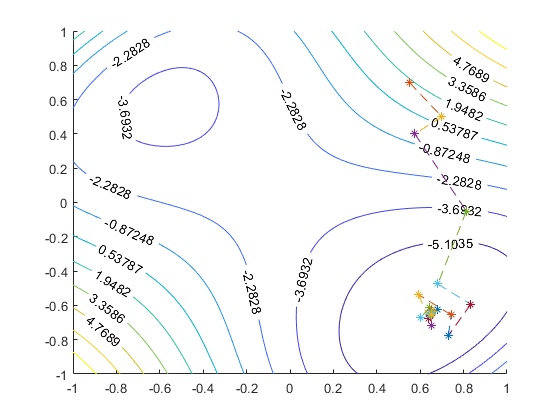

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1



%Starting Point
x0=[0.55;0.7];
N=3;  %%%%%%%%%PLEASE DECIDE THE NO. OF POINTS ACCORDING TO DIMENSIONS OF STARTING POINT %%%%%%%%%%%%%

% Inputs
lamda=0.1; e1=[1 0]'; e2=[0 1]'; ro=1; chi=2; gamma=1/2; sigma=1/2;

% So for a two dimensional function we must have n+1 points so following
% are three points
x(:,3)=x0;
x(:,1)=x0+lamda*e1;
x(:,2)=x0+lamda*e2;

%Plot
hold on
[X1,X2]=meshgrid(-1:0.01:1);
Y=(X2-X1).^4+12.*X1.*X2-X1+X2-3; %% <-- CHANGE CONTOUR FUNCTION %%%%%%%%
[V,h] = contour(X1,X2,Y,10);
clabel(V,h);
plot(x0(1),x0(2),'--*')

while true

    z=x(:,3);
    % Sorting the matrix to arrange in the ascending order of objective
    % function values
    for i=1:(N-1)
        for j=1:(N-i)
            if(fun(x(:,j))> fun(x(:,j+1)))
            a=x(:,j);
            x(:,j)=x(:,j+1);
            x(:,j+1)=a;
            end
        end
    end
    x=x;
    
    % Stopping Criteria
    size=norm(x(:,1)-x(:,2))+norm(x(:,2)-x(:,3))+norm(x(:,3)-x(:,1));
    if (size<1e-6)
        break;
    end
    % Finding Centroid Point
    Pg=1/2*((x(:,1)+x(:,2))); %note x(:,1) is smallest point , x(:,2) is next largest point
    
    % Checking Different Points
    % 1) Reflection Point
    Pr=Pg+ro*(Pg-x(:,3));
    if (fun(Pr)>=fun(x(:,1)) && fun(Pr)<fun(x(:,2)))
        x(:,3)=Pr;
    elseif (fun(Pr)<fun(x(:,1)))
        % 2) Expansion Move
        Pe=Pg+chi*(Pr-Pg);
        if (fun(Pe)<fun(Pr))
            x(:,3)=Pe;
        else
            x(:,3)=Pr;
        end
    elseif (fun(Pr)>fun(x(:,2)) && fun(Pr)<fun(x(:,3)))
        % 3) Outside Contraction Move
        Pc=Pg+gamma*(Pr-Pg);
        if (fun(Pc)<fun(x(:,3)))
            x(:,3)=Pc;
        end
    else (fun(Pr)>fun(x(:,3)))
        % 4) Inside Contraction Move
        Pcc=Pg+gamma*(x(:,3)-Pg);
        if fun(Pcc)<fun(x(:,3))
            x(:,3)=Pcc;
        else
            x(:,2)=1/2*(x(:,1)+x(:,2));
            x(:,3)=1/2*(x(:,1)+x(:,3));
        end
    end
     plot([z(1),x(1,3)],[z(2),x(2,3)],'--*');
end

x(:,1)

ans =     0.6504
   -0.6504


function y = fun(x)
    y=(x(1)-x(2))^4+12*x(1)*x(2)-x(1)+x(2)-3;
end